# Gaussian beam visualization

Parameters.  All lengths are in [m].

clear
E0 = 1.0;        % Electric field amplitude
lam = 500e-9;    % Wavelength in meters
zR = 5e-6;       % Rayleigh range in meters

% Wavenumber calculation
k = 2*pi/lam

k = 1.2566e+07

Plot $w(z)$ and $R(z)$.

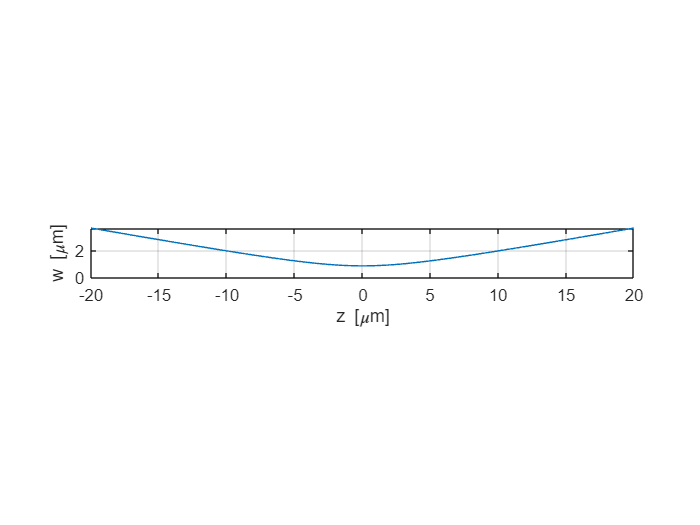

% Define z-axis range for plotting w(z) and R(z)
dz = lam/10;     % z-axis increment
z = -4*zR:dz:4*zR;
nz = length(z);  % Number of z points

% Calculate w0, w(z), and R(z)
w0 = sqrt(2*zR/k);
w = w0 * sqrt(1+(z/zR).^2);
R = z .* (1+(zR./z).^2);

% Plot w(z)
figure
plot(z*1e6, w*1e6)
axis image
ax = gca;
ax.YLim = [0 1] * max(ax.YLim);
grid on
xlabel('z [\mum]')
ylabel('w [\mum]')

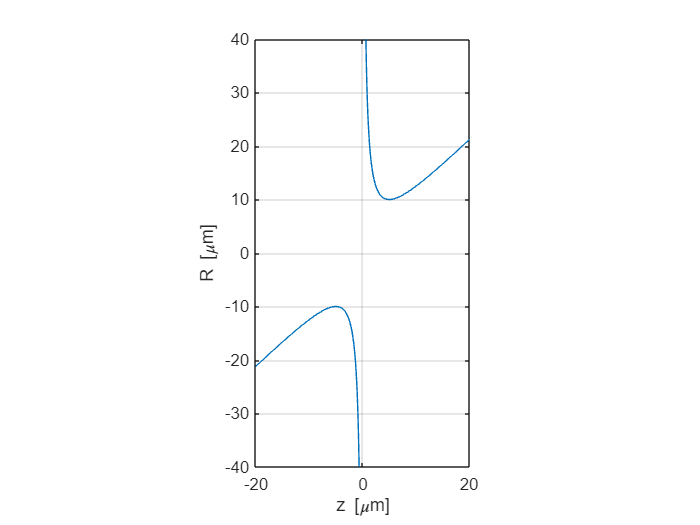


% Plot R(z)
figure
plot(z*1e6, R*1e6)
axis image
ylim([-1 1]*max(z)*2*1e6)
grid on
xlabel('z [\mum]')
ylabel('R [\mum]')

Visualize $E(\rho,z)$ and its intensity.

rho = 0:dz:2*zR;  % Define rho range
nrho = length(rho);
[grho, gz] = ndgrid(rho, z);  % Create 2D grid
size(grho)

ans =    201   801


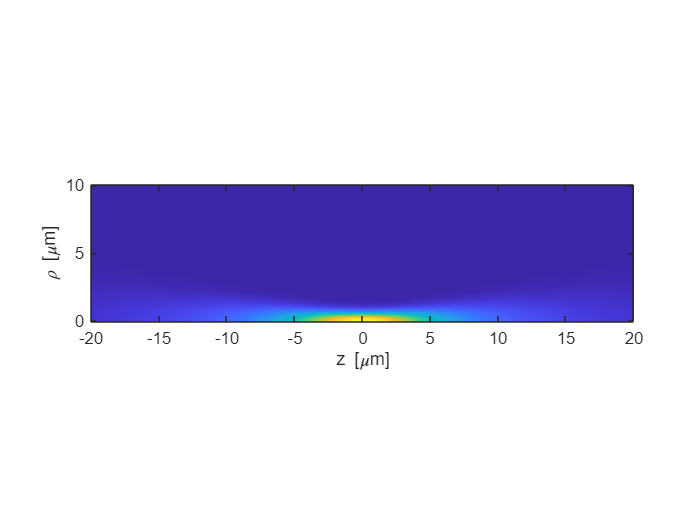


% Recalculate w and R for 2D arrays
w = w0 * sqrt(1+(gz/zR).^2);
R = gz .* (1+(zR./gz).^2);
R(isnan(R)) = Inf;  % Replace NaNs with Infinity
zeta = atan(gz/zR);

E = E0/zR * w0 ./ w .* exp(-grho.^2 ./ w.^2) .* exp(1i*( k/2./R.*grho.^2 + pi/2 - zeta + k*z));
I = E .* conj(E);
I = abs(E).^2;  % same as above

% Plot intensity pattern
figure
imagesc(z * 1e6, rho * 1e6, I)  % Convert to micrometers for plotting
axis image
set(gca, 'YDir', 'normal')
xlabel('z [\mum]')
ylabel('\rho [\mum]')

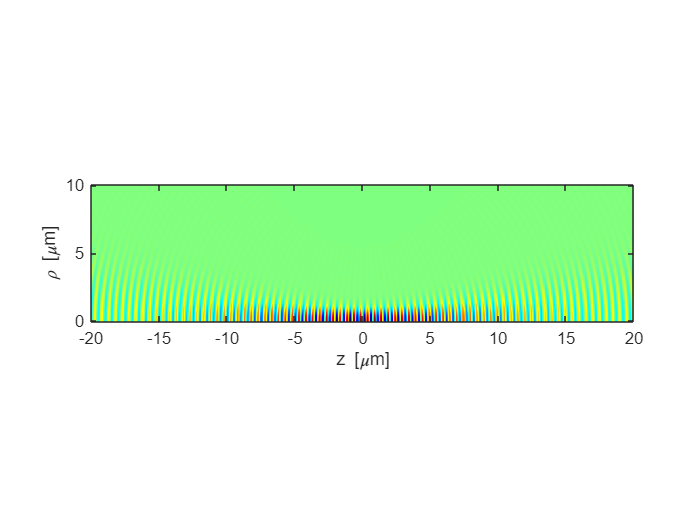


% Plot real part of E field
figure
colormap(jet)
imagesc(z * 1e6, rho * 1e6, real(E))
axis image
set(gca, 'YDir', 'normal')
xlabel('z [\mum]')
ylabel('\rho [\mum]')

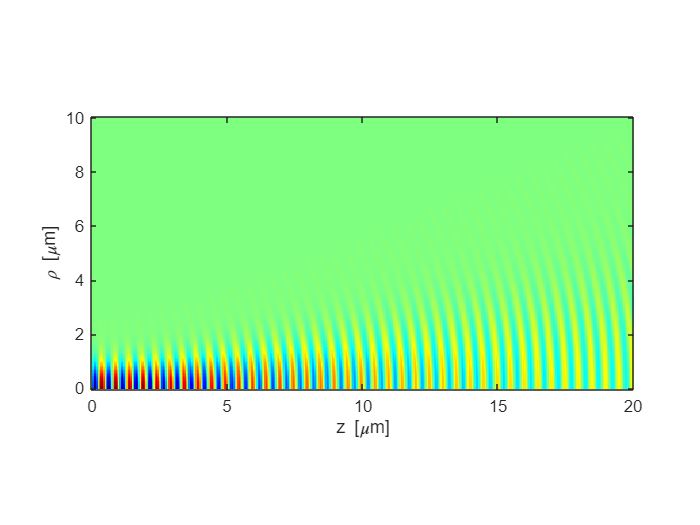


figure
colormap(jet)
imagesc(z(round(end/2):end)*1e6,rho*1e6,real(E(:,round(end/2):end)))
set(gca,'ydir','normal')
axis image
xlabel('z [\mum]')
ylabel('\rho [\mum]')

Plot $I(\rho)$ at several z positions.

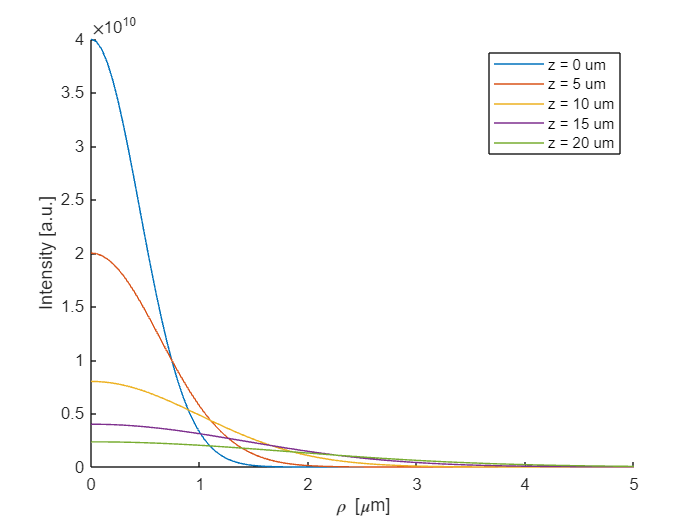

zs = (0 : 5e-6 : max(z));  

clr = lines(numel(zs));
figure
hold on
for iz = 1 : numel(zs)
    z1 = zs(iz);
    [~, iz1] = min(abs(z - z1));
    plot(rho * 1e6, I(:, iz1), 'Color', clr(iz, :))  % Convert to micrometers for plotting   
end
hold off
xlim([0, 5])
legend(compose('z = %g um', zs * 1e6))
xlabel('\rho [\mum]')
ylabel('Intensity [a.u.]')